%% Clear temporary variables
clear variables

# 1D Exemple - Rhine River Discharge

## This section imports data from a CSV file containing measurements of river discharge and water levels.

The following commands were auto-generated by MATLAB on 29-Oct-2024 to extract data

%% Set up the Import Options and import the data
% Define the import options for reading the CSV file.
opts = delimitedTextImportOptions("NumVariables", 5); % Specify that there are 5 variables in the file.

% Specify the range of data to read and the delimiter used in the CSV file.
opts.DataLines = [2, Inf]; % Start reading data from the second line to the end.
opts.Delimiter = ","; % Set the delimiter to a comma.

% Specify column names and their corresponding data types.
opts.VariableNames = ["VarName1", "Zeitstempel", "Abflussmenge", "Pegel", "Wasserstand"]; % Column names in the CSV.
opts.VariableTypes = ["double", "string", "double", "double", "double"]; % Data types for each column.

% Set additional properties for handling extra and empty columns.
opts.ExtraColumnsRule = "ignore"; % Ignore any extra columns in the file.
opts.EmptyLineRule = "read"; % Read empty lines as valid.

% Set properties for specific variables.
opts = setvaropts(opts, "Zeitstempel", "WhitespaceRule", "preserve"); % Preserve whitespace in the 'Zeitstempel' column.
opts = setvaropts(opts, "Zeitstempel", "EmptyFieldRule", "auto"); % Automatically handle empty fields in 'Zeitstempel'.

% Import the data from the CSV file into a table and then convert it to an array.
riverrhine = readtable("C:\Users\dany-\OneDrive\Bureau\Projets\Article9_GeoSpatioFFT\E6 - Rhine River\river_rhine.csv", opts);
riverrhine = table2array(riverrhine); % Convert the table to a numerical array.

%% Clear temporary variables
% Clear the temporary variable used for importing options to free up memory.
clear opts


## Extract specific columns from the imported data.

x0 = str2double(riverrhine(:,1)); % Convert the first column to double (time indices).
Z = str2double(riverrhine(:,3));  % Extract the discharge data (third column).


## Determine the dimensions of the data for further analysis.

nx = length(x0); % Number of time points.
ny = 1; % Number of variables (1 in this case).


## Dataset of the time series (5 min) of the Rhine River discharge at the Basel station

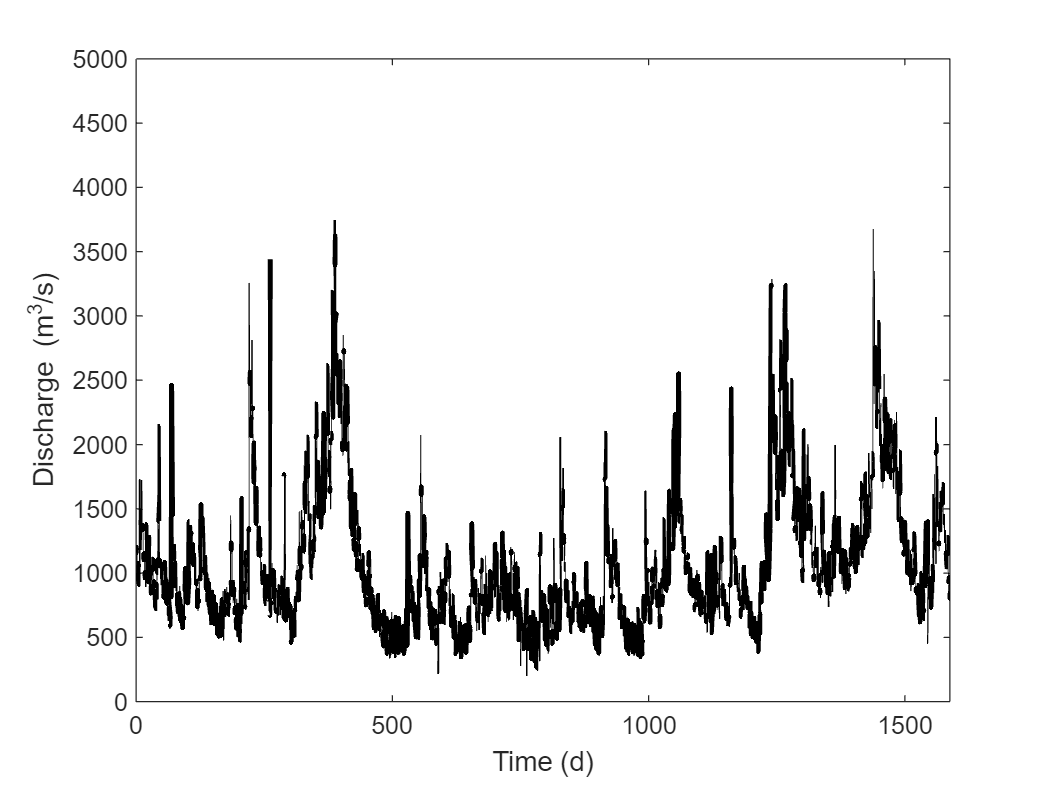

% Create a figure to plot the time series of river discharge.
figure(100)
set(gcf, 'Position', [200, 200, 800, 250]); % Adjust figure size to reduce white space.
plot(x0*5/60/24, Z,'-k', 'LineWidth', 1); % Plot discharge over time in black.
hold on 
plot([210 250 250 210 210], [500 500 3500 3500 500],'-r', 'LineWidth', 1)
xlabel('Time (d)') % Time in days.
ylabel('Discharge (m^3/s)') % Discharge in cubic meters per second.
xlim([0 length(x0)*5/60/24]) % Set x-axis limits based on the length of the data.
ylim([0 4000]) % Set y-axis limits.
pbaspect([4 1 1]) % Adjust axis ratio

% Save the figure with reduced white space.
print('E6 - Rhine River/TimeSeries', '-depsc', '-r300', '-loose'); % '-r300' for high resolution, '-loose' to tighten borders.

## Compute the variograms and cross-variograms

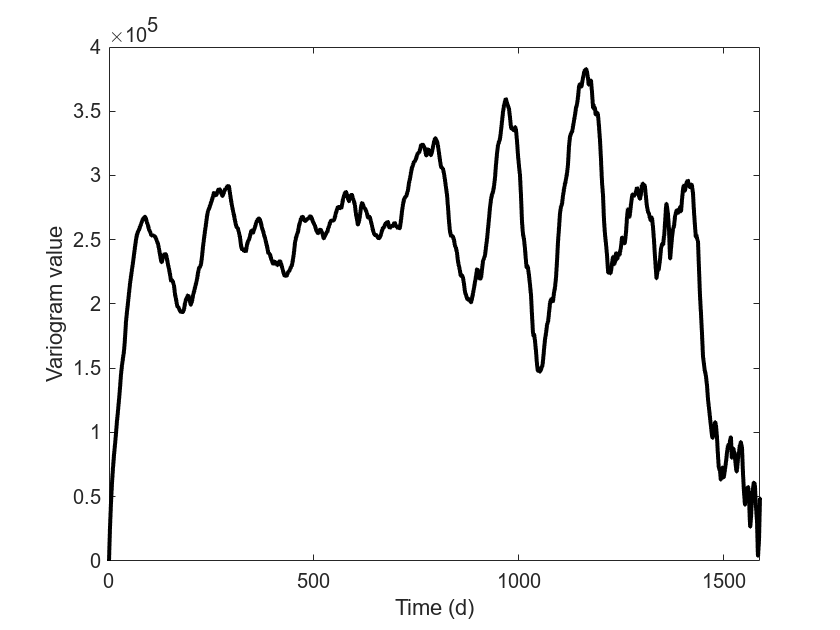

% Set the code to compute variograms (icode = 1).
icode = 1;
gh = GeoStatFFT(x0, Z, icode); % Call GeoStatFFT function to compute variograms.

% Create a new figure for variogram plots.
figure(1)
plot(x0*5/60/24, gh{1,1}(nx:end, ny), '-k', 'LineWidth', 2) % Plot the computed variogram in black.
xlabel('Time (d)') % Time in days.
ylabel('Variogram value')
xlim([0 length(x0)*5/60/24]) % Set x-axis limits based on the length of the data.

**Compute the covariograms and cross-covariograms**

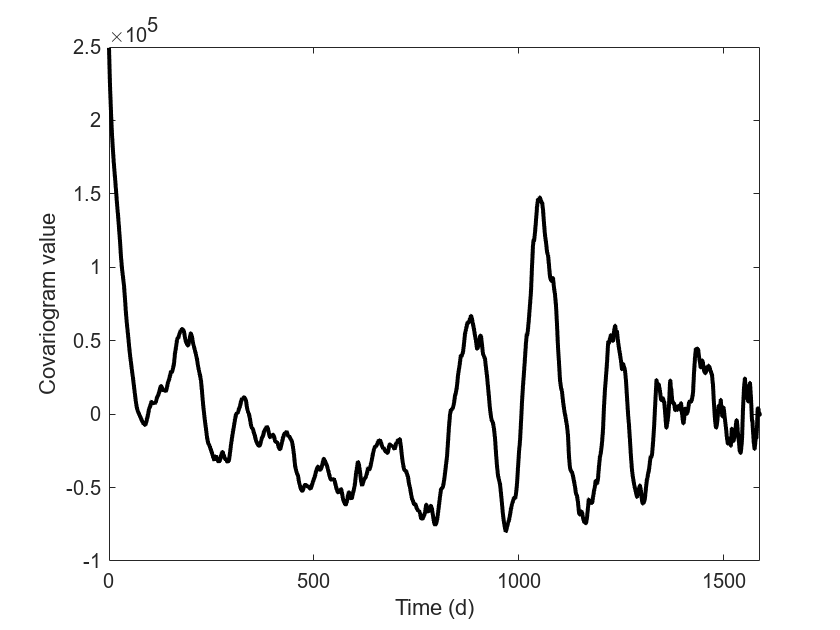

% Set the code to compute covariograms (icode = 2).
icode = 2;
gh = GeoStatFFT(x0, Z, icode); % Call GeoStatFFT function to compute covariograms.

% Create a new figure for covariogram plots.
figure(2)
plot(x0*5/60/24, gh{1,1}(nx:end, ny), '-k', 'LineWidth', 2) % Plot the computed covariogram in black.
xlabel('Time (d)') % Time in days.
ylabel('Covariogram value') 
xlim([0 length(x0)*5/60/24]) % Set x-axis limits based on the length of the data.

## Compute the centered covariances and cross-covariances

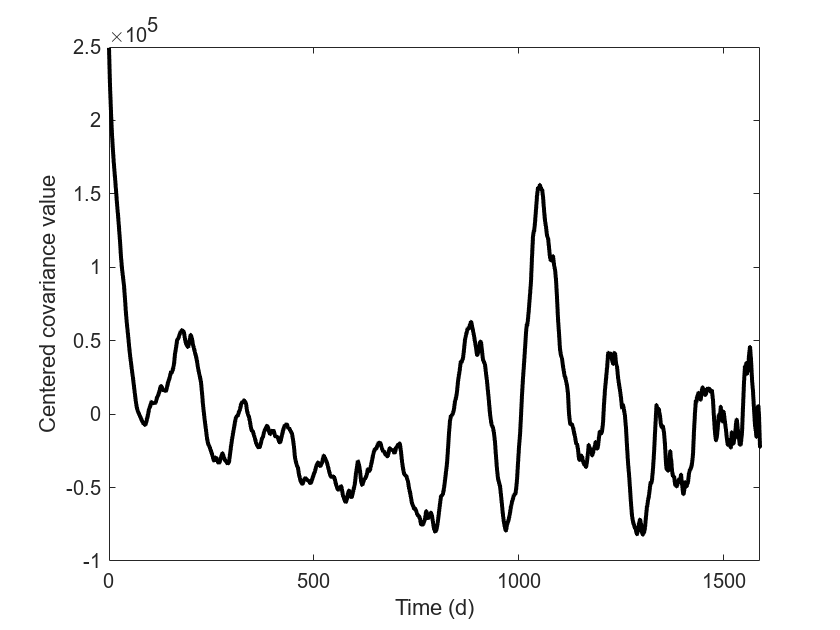

% Set the code to compute centered covariances (icode = 4).
icode = 4;
gh = GeoStatFFT(x0, Z, icode); % Call GeoStatFFT function to compute centered covariances.

% Create a new figure for centered covariance plots.
figure(4)
plot(x0*5/60/24, gh{1,1}(nx:end, ny), '-k', 'LineWidth', 2) % Plot the computed centered covariance in black.
xlabel('Time (d)') % Time in days.
ylabel('Centered covariance value')
xlim([0 length(x0)*5/60/24]) % Set x-axis limits based on the length of the data.

## Compute the non-centered covariances and cross-covariances

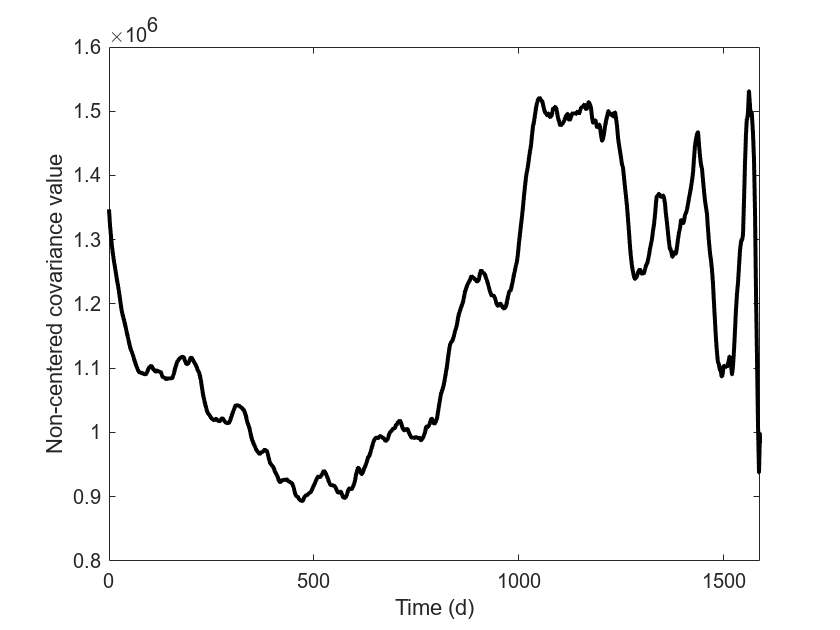

% Set the code to compute non-centered covariances (icode = 5).
icode = 5;
gh = GeoStatFFT(x0, Z, icode); % Call GeoStatFFT function to compute non-centered covariances.

% Create a new figure for non-centered covariance plots.
figure(5)
plot(x0*5/60/24, gh{1,1}(nx:end, ny), '-k', 'LineWidth', 2) % Plot the computed non-centered covariance in black.
xlabel('Time (d)') % Time in days.
ylabel('Non-centered covariance value')
xlim([0 length(x0)*5/60/24]) % Set x-axis limits based on the length of the data.

## Compute the directional asymmetry

% Set the code to compute directional asymmetry (icode = 8).
icode = 8;
gh = GeoStatFFT(x0, Z, icode, 0, 0, 1); % Call GeoStatFFT for directional asymmetry.

Nx = length(x0); % Number of time points.
% Simulate random fields with specified parameters.
[z] = fftma([2 23000/2.5], 267216, 412, 100, Nx, 1);
for i = 1:100 % Loop over 100 simulations
    gh1{i} = GeoStatFFT(x0(1:Nx,:), z(:,i), icode, 0, 0, 1); % Store results from each simulation.
end
% Create a new figure to plot directional asymmetry.
figure(6)
gmean = []; % Initialize a matrix to store means of asymmetry values.
for i = 1:100
    h1 = plot(x0*5/60/24 , gh1{i}{1,1}(Nx:end), 'color', [0.9 0.9 0.9], 'LineWidth', 1); % Plot each simulation in light gray.
    hold on
    gmean(:,i) = gh1{i}{1,1}(Nx:end); % Store the asymmetry values for averaging.
end
h2 = plot(x0*5/60/24, mean(gmean, 2), '-k', 'LineWidth', 2); % Plot the mean asymmetry in black.
hold on
plot(x0*5/60/24, quantile(gmean, 0.05, 2), '--k', 'LineWidth', 2); % Plot the 5th percentile quantile.
hold on
h3 = plot(x0*5/60/24, quantile(gmean, 0.95, 2), '--k', 'LineWidth', 2); % Plot the 95th percentile quantile.
hold on
h4 = plot(x0*5/60/24, gh{1,1}(nx:end), '-g', 'LineWidth', 2); % Plot the directional asymmetry in green.
xlim([0 20]) % Set x-axis limits to cover 20 days.
xlabel('Time (d)','FontSize',12) % X-axis label in French.
ylabel('Directional asymmetry value','FontSize',12) % Y-axis label in French.
legend([h1 h2 h3 h4], {'Gaussian random field (GRF)', 'GRF average', '95% C.I. of GRF', 'Rhine River directional asymmetry'}); % Legend for the plot.

## **Compute the variogram of the 100 realizations**

% Set the code to compute the variogram again (icode = 1).
icode = 1;
gh = GeoStatFFT(x0, Z, icode, 0, 0, 1); % Call GeoStatFFT to compute the variogram.

Nx = length(x0); % Number of time points.
% Simulate random fields with specified parameters.
[z] = fftma([2 23000/2.5], 267216, 412, 100, Nx, 1);
for i = 1:100 % Loop over 100 simulations
    gh1{i} = GeoStatFFT(x0(1:Nx,:), z(:,i), icode, 0, 0, 1); % Store results from each simulation.
end

% Create a new figure to plot the variogram.
figure(7)
gmean = []; % Initialize a matrix to store means of asymmetry values.
for i = 1:100
    h1 = plot(x0*5/60/24, gh1{i}{1,1}(Nx:end), 'color', [0.9 0.9 0.9], 'LineWidth', 1); % Plot each simulation in light gray.
    hold on
    gmean(:,i) = gh1{i}{1,1}(Nx:end); % Store the asymmetry values for averaging.
end
h2 = plot(x0*5/60/24, mean(gmean, 2), '-k', 'LineWidth', 2); % Plot the mean asymmetry in black.
hold on
plot(x0*5/60/24, quantile(gmean, 0.05, 2), '--k', 'LineWidth', 2); % Plot the 5th percentile quantile.
hold on
h3 = plot(x0*5/60/24, quantile(gmean, 0.95, 2), '--k', 'LineWidth', 2); % Plot the 95th percentile quantile.
hold on
h4 = plot(x0*5/60/24, gh{1,1}(nx:end), '-g', 'LineWidth', 2); % Plot the directional asymmetry in green.
xlim([0 100]) % Set x-axis limits to cover 20 days.
ylim([0 4.5*10^5]) % Set y-axis limits to start at 0s.
xlabel('Time (d)','FontSize',12) % X-axis label in French.
ylabel('Variogram value','FontSize',12) % Y-axis label in French.
legend([h1 h2 h3 h4], {'Gaussian random field (GRF)', 'GRF average', '95% C.I. of GRF', 'Rhine River variogram'}); % Legend for the plot.